# **SISTEMAS DE CONTROL **

# 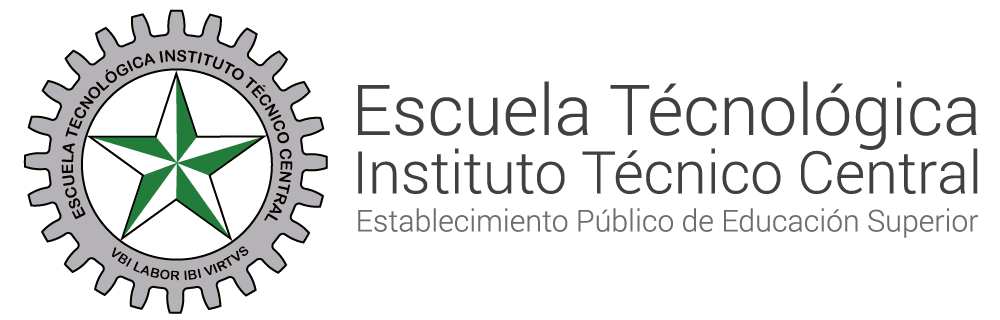

# **Estabilidad**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO 

En sistema de control se considera BIBO estable si, para cualquier entrada acotada (limitada), la salida también está acotada y no crece infinitamente con el tiempo. Esto significa que las perturbaciones o entradas limitadas no provocarán una respuesta incontrolada en el sistema.

- Los polos son las raíces del denominador de la función de transferencia de un sistema. Son los valores de *s* que hacen que el denominador sea igual a cero.

- Los ceros son las raíces del numerador de la función de transferencia. Son los valores de *s* que hacen que el numerador sea igual a cero

#### Criterio Routh-Hurwitz

El criterio de RH representa un método para determinar la localización de los ceros de un polinomio con coeficientes constantes reales con respecto a los semiplanos izquierdo y derecho del plano s, sin obtener los ceros. Debido a que los programas para computadoras  para encontrar raíces pueden resolver los ceros de un polinomio con facilidad, el valor del criterio de R-H esta limitado a ecuaciones con por lo menos un parámetro desconocido.


$$P\left(s\right)=a_n s^n +a_{n-1} s^{n-1} {+a}_{n-2} s^{n-2} \ldotp \ldotp \ldotp a_0 s^0$$


Lo primero es entender que tenemos una expresion de la forma 


$$1+G\left(s\right)=0$$


En donde $G\left(s\right)$es una funcion de transferencia multiplicado por $K$, donde $K$es la ganancia del sistema haciendo que sea estable este.


$$1+G\left(s\right)=1+K\frac{F\left(s\right)}{D\left(s\right)}=0$$


**Paso 1**

Arreglar los coeficientes de la ecuación en dos renglones, el primer renglón consiste del primero, tercero, quinto, etccoeficiente y el segundo renglón consisten del segundo, cuarto, sexto, etccoeficientes.

**Paso 2**

Formar el siguiente arreglo de números mediante las operaciones ilustradas aquí

syms A B C a0 a1 a2 a3 a4 a5 a6 

tabla_routh = [a6, a4, a2, a0;  
               a5, a3, a1, 0;  
               (a5*a4-a6*a3)/a5, (a5*a2-a6*a1)/a5, a0, 0;  
               d2, d1, 0, 0;
               e1, 0, 0, 0;
               f1, 0, 0, 0]; 

tabla = array2table(tabla_routh, ...
    'VariableNames', {'Columna_1', 'Columna_2', 'Columna_3','Columna_4'}, ...
    'RowNames', {'s^5', 's^4', 's^3', 's^2','s^1','s^0'});
disp(tabla);

                Columna_1              Columna_2         Columna_3    Columna_4
           ___________________    ___________________    _________    _________

    s^5    a6                     a4                        a2           a0    
    s^4    a5                     a3                        a1           0     
    s^3    -(a3*a6 - a4*a5)/a5    -(a1*a6 - a2*a5)/a5       a0           0     
    s^2    d2                     d1                        0            0     
    s^1    e1                     0                         0            0     
    s^0    f1                     0                         0            0     



Ejemplo

Considere las ecuaciones anteriores, mediante el criterio de polos y ceros y RH determine si son es estables o inestable.


$$P\left(s\right)=s^3 +3408\ldotp 3s^2 +1204000s+1\ldotp 5{\mathrm{x10}}^7 k$$
